In this, we will extend the code of pca_all and add a neural network after pca which will do the job of predicting.

We take the best value of k found there, k = 100

Creating the train and test file

addpath("lib/")

accuracy = 0;
k  = 100;
load YaleB_32x32.mat
%accuracy = 0;
num_of_passes = 0;
%for iter=0:10    
    [data_size,image_size] = size(fea);
    image_size = sqrt(image_size);
    test_index = randi(data_size,1,100);
    train_index = 1:data_size;
    train_index(test_index) = [];
    
    train_face = fea(train_index,:)';
    train_label = gnd(train_index,:);
    test_face = fea(test_index,:)';
    test_label = gnd(test_index,:);
    train_size = size(train_index,2);
    test_size = size(test_index,2);

Mean

    train_mean = mean(train_face,2);
    train_face = train_face - train_mean;

Eigen-faces

    [eigen_faces,eigen_value,~] = svd(train_face'*train_face);
    eigen_faces = normc(train_face*eigen_faces);
    eigen_faces = eigen_faces(:,4:k+3); 
    eigen_value = diag(eigen_value);
    eigen_value = eigen_value(4:k+3)';

Projection

    train_weights = eigen_faces' * train_face;

Training the model

    nnOptions = {'lambda', 0.001, 'maxIter', 100000, 'hiddenLayers', [1000 500 250 100], 'activationFn', 'tanh', 'validPercent', 20, 'doNormalize', 1};
    model = learnNN(train_weights',train_label,nnOptions);

Iteration     1 | Cost: 1.494286e+01
Iteration     2 | Cost: 4.118754e+00
Iteration     3 | Cost: 3.407379e+00
Iteration     4 | Cost: 2.547319e+00
Iteration     5 | Cost: 1.856541e+00
Iteration     6 | Cost: 1.360609e+00
Iteration     7 | Cost: 1.011927e+00
Iteration     8 | Cost: 6.823752e-01
Iteration     9 | Cost: 4.841397e-01
Iteration    10 | Cost: 3.436052e-01
Iteration    11 | Cost: 2.302344e-01
Iteration    12 | Cost: 1.848640e-01
Iteration    13 | Cost: 1.201293e-01
Iteration    14 | Cost: 9.249776e-02
Iteration    15 | Cost: 5.961896e-02
Iteration    16 | Cost: 3.513474e-02
Iteration    17 | Cost: 3.216384e-02
Iteration    18 | Cost: 2.879928e-02
Iteration    19 | Cost: 1.929631e-02
Iteration    20 | Cost: 1.500259e-02
Iteration    21 | Cost: 1.370602e-02
Iteration    22 | Cost: 1.240971e-02
Iteration    23 | Cost: 1.187532e-02
Iteration    24 | Cost: 1.114800e-02
Iteration    25 | Cost: 1.046780e-02
Iteration    26 | Cost: 9.590311e-03
Iteration    27 | Cost: 9.198199e-03
I

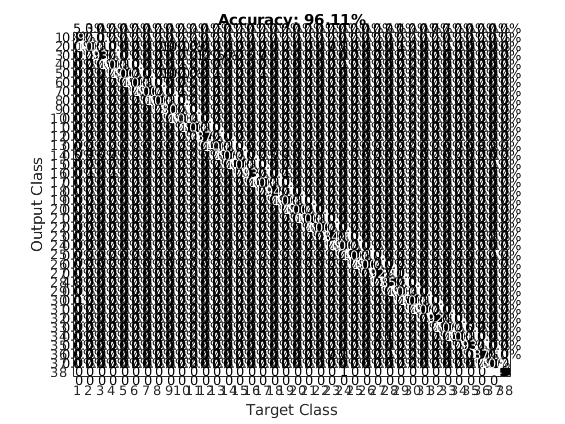

    figure(1); cla(gca);
    plotConfMat(model.confusion_valid);

Testing the model

    test_weights = eigen_faces'*(test_face - train_mean);
    for i = 1:test_size
        pred = predictNN(test_weights(:,i)',model);
        if pred == test_label(i)
            accuracy=accuracy+1;
        end
    end
%end
disp(accuracy);

    98



%    nnOptions = {'lambda', 0.01, 'maxIter', 10000, 'hiddenLayers', [1000 500 200 75], 'activationFn', 'tanh', 'validPercent', 30, 'doNormalize', 1};
